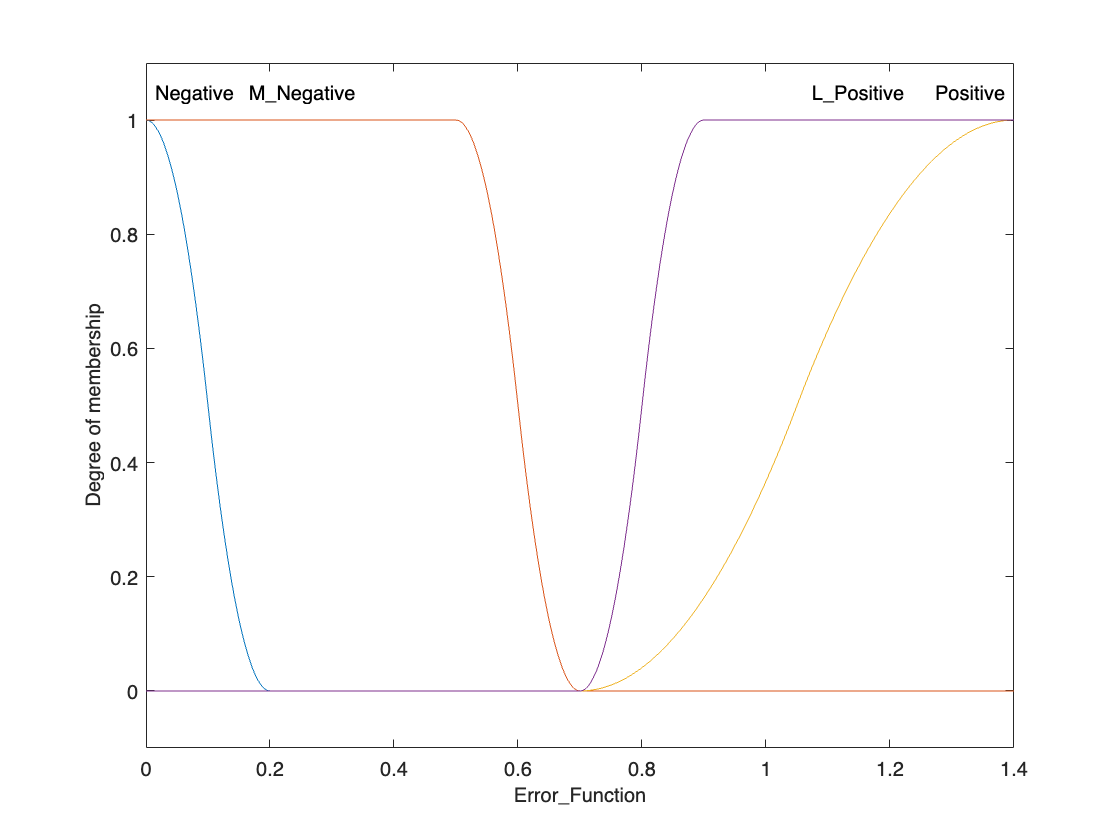

%Neurofeedback Fuzzy inference system
%% Version V4
% Authors - Mario De Los Santos, Felipe Orihuela-Espina, Javier
% Herrara-Vega, Gustavo Rodriguez 
% Date - April 20st, 2022
% Email - madlsh3517@gmail.com

cFNIRS_c = mamfis(...
    'NumInputs', 1, 'NumInputMFs', 1, ...
    'NumOutputs', 1, 'NumOutputMFs', 4, ...
    'AddRule', 'none');

%Inputs

cFNIRS_c.Inputs(1).Name = 'Error_Function';
cFNIRS_c.Inputs(1).Range = [0, 1.4]; 
cFNIRS_c.Inputs(1).MembershipFunctions(1).Name = 'Negative';
cFNIRS_c.Inputs(1).MembershipFunctions(1).Type ='zmf'; %Z-shaped memebership function
cFNIRS_c.Inputs(1).MembershipFunctions(1).Parameters = [0 0.2];

cFNIRS_c.Inputs(1).MembershipFunctions(2).Name = 'M_Negative';
cFNIRS_c.Inputs(1).MembershipFunctions(2).Type ='zmf'; %Z-shaped memebership function
cFNIRS_c.Inputs(1).MembershipFunctions(2).Parameters = [0.5 0.7];

cFNIRS_c.Inputs(1).MembershipFunctions(4).Name = 'L_Positive';
cFNIRS_c.Inputs(1).MembershipFunctions(4).Type ='smf'; %S-shaped memebersh
cFNIRS_c.Inputs(1).MembershipFunctions(4).Parameters = [0.7 0.9];

cFNIRS_c.Inputs(1).MembershipFunctions(3).Name = 'Positive';
cFNIRS_c.Inputs(1).MembershipFunctions(3).Type ='smf'; %S-shaped memebersh
cFNIRS_c.Inputs(1).MembershipFunctions(3).Parameters = [0.7 1.4];


plotmf(cFNIRS_c, 'input', 1, 1000);

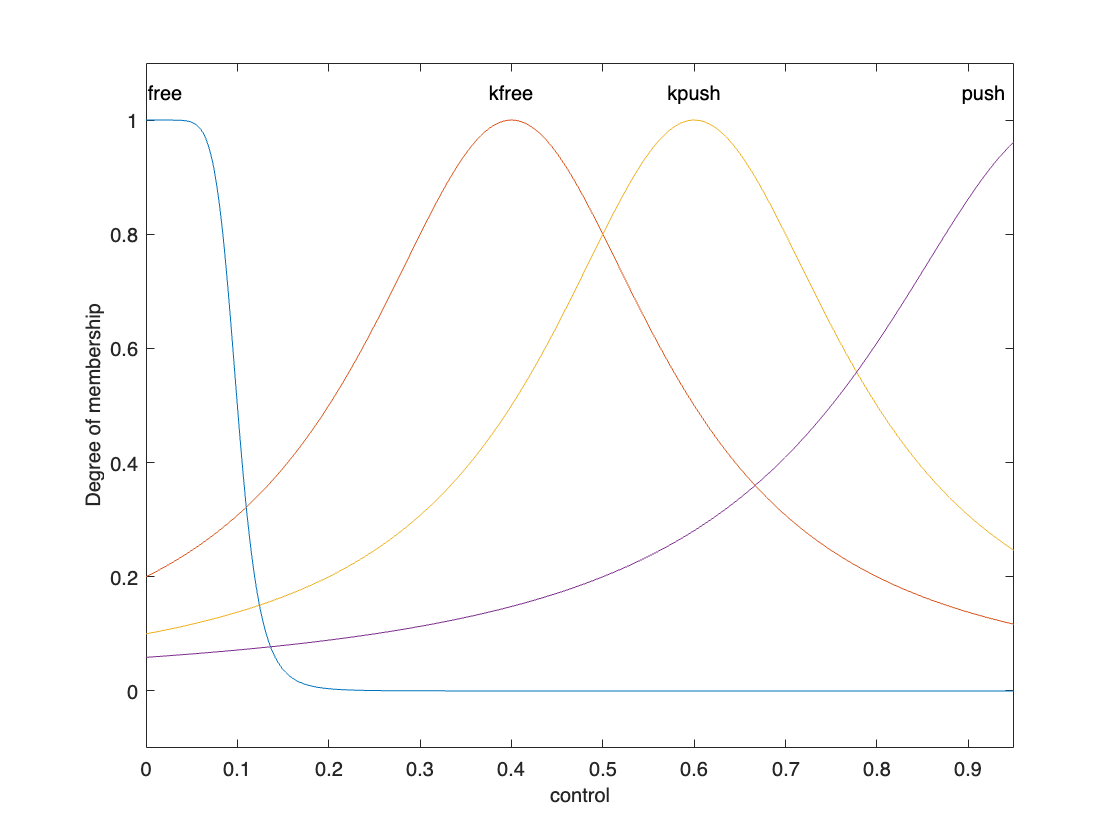

% Outputs
cFNIRS_c.Outputs(1).Name = 'control';
cFNIRS_c.Outputs(1).Range = [0,0.95];

cFNIRS_c.Outputs(1).MembershipFunctions(1).Name = 'free'; %Negative Low alternative
cFNIRS_c.Outputs(1).MembershipFunctions(1).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS_c.Outputs(1).MembershipFunctions(1).Parameters = [0.1,4,0];

cFNIRS_c.Outputs(1).MembershipFunctions(2).Name = 'kfree'; %Negative Low alternative
cFNIRS_c.Outputs(1).MembershipFunctions(2).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS_c.Outputs(1).MembershipFunctions(2).Parameters = [0.2,1,0.4];

cFNIRS_c.Outputs(1).MembershipFunctions(3).Name = 'kpush'; %Negative Low alternative
cFNIRS_c.Outputs(1).MembershipFunctions(3).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS_c.Outputs(1).MembershipFunctions(3).Parameters = [0.2,1,0.6];

cFNIRS_c.Outputs(1).MembershipFunctions(4).Name = 'push'; %Negative Low alternative
cFNIRS_c.Outputs(1).MembershipFunctions(4).Type = 'gbellmf'; %Generalized bell-shaped membership function
cFNIRS_c.Outputs(1).MembershipFunctions(4).Parameters = [0.25,1,1];


plotmf(cFNIRS_c, 'output', 1, 1000);

%rules
rules = ["If Error_Function is Positive then control is kfree";...
         "If Error_Function is Negative then control is free";...
         "If Error_Function is M_Negative then control is free";...
         "If Error_Function is L_Positive then control is push"];

cFNIRS_c = addRule(cFNIRS_c,rules);